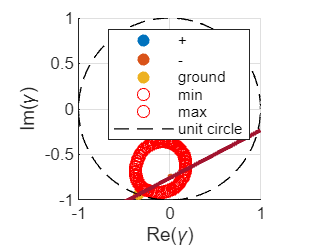

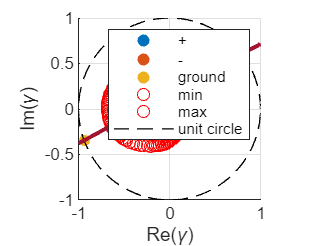

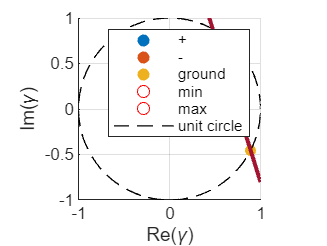

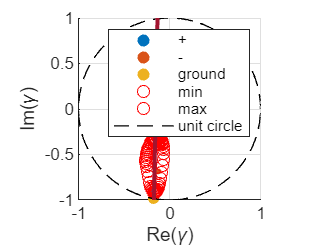

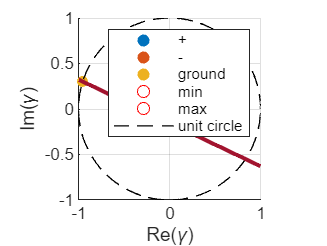

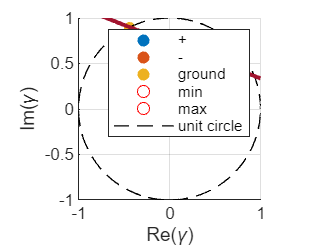

clear;

fileNames = ["data/c3x7_s1602_l48.m","data/c3x7_s1794_l290.m","data/c3x7_s1914_l275.m","data/c7x17_s1602_l48.m","data/c7x17_s1794_l290.m","data/c7x17_s1914_l275.m"];
P_values = zeros(6, 2);
% sol_values = zeros(6,2, 2);
% cut_values = zeros(6,2);
for l=1:6
boundary_N = 60;
fileName = fileNames(l);
run(fileName);
CoherencePoints = PauliBasesPoints(fileName);
boundary_vals = BoundaryScan(fileName, boundary_N);

P = linortfit(real(CoherencePoints), imag(CoherencePoints));
P_values(l, :) = P;

% syms x y 
% eqn=[P(1)+P(2)*x==y,sqrt(x^2+y^2)==1];
% [sol_values(l,1,:), sol_values(l,2,:)]=solve(eqn,[x y]);
% distancesum1=sqrt((sol_values(l,1,1)-real(CoherencePoints(1)))^2+(sol_values(l,2,1)-imag(CoherencePoints(1)))^2);
% distancesum2=sqrt((sol_values(l,1,2)-real(CoherencePoints(1)))^2+(sol_values(l,2,2)-imag(CoherencePoints(1)))^2);
% distancediff1=sqrt((sol_values(l,1,1)-real(CoherencePoints(2)))^2+(sol_values(l,2,1)-imag(CoherencePoints(2)))^2);
% distancediff2=sqrt((sol_values(l,1,2)-real(CoherencePoints(2)))^2+(sol_values(l,2,2)-imag(CoherencePoints(2)))^2);
% if distancediff1>distancesum1
%     cut_values(l,:)=sol_values(l,:,1);
% else
%     cut_values(l,:)=sol_values(l, :, 2);
% end

groundPoint = findGround(P, CoherencePoints);

% --- Plot the brute-force sampled points ---
figure('Name','Coherence points','NumberTitle','off');
hold on;  % keep all plots in the same figure
axis equal; grid on;

% scatter plot of your samples
scatter(real(CoherencePoints(1)), imag(CoherencePoints(1)), 8, 'filled');
scatter(real(CoherencePoints(2)), imag(CoherencePoints(2)), 8, 'filled');
scatter(real(groundPoint(1)), groundPoint(2), 30, 'filled');
scatter(real(boundary_vals(:,1)), imag(boundary_vals(:,1)), 'ro', 'red');
scatter(real(boundary_vals(:,2)), imag(boundary_vals(:,2)), 'ro', 'red');

% draw unit circle for reference
th = linspace(0,2*pi,500);
plot(cos(th), sin(th), 'k--', 'LineWidth', 0.7);
q = linspace(-1, 1, 100);
plot(q,P(1)+P(2)*q, 'LineWidth', 2);
% labels and title
xlabel('Re(\gamma)'); 
ylabel('Im(\gamma)');
xlim([-1 1]);
ylim([-1 1]);

% legend
legend('+','-','ground','min','max', 'unit circle');

hold off;  % optional, release hold

end


writematrix(P_values, "PauliPoints_OR_Values");